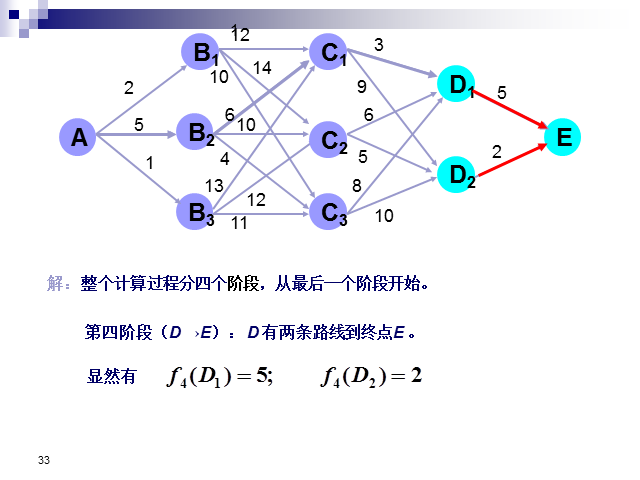

clc;clear
%% 准备邻接矩阵
n=10;
a=zeros(n);
%A1-B3
a(1,2)=2;  a(1,3)=5;  a(1,4)=1;
%B3-C3
a(2,5)=12; a(2,6)=14; a(2,7)=10;
a(3,5)=6;  a(3,6)=10; a(3,7)=4;
a(4,5)=13; a(4,6)=12; a(4,7)=11;
%C3-D2
a(5,8)=3;  a(5,9)=9;
a(6,8)=6;  a(6,9)=5;
a(7,8)=8;  a(7,9)=10;
%D2-E1
a(8,10)=5;
a(9,10)=2;
a(a==0)=inf;
%记录节点在邻接矩阵中的位置
b=[1,1;2,3;5,3;8,2;10,1];
stage=4;%阶段数

%% 动态规划的3层循环
%第一层循环为stage阶段循环
fk_next=0;
dk_num=zeros(n-1,1);
count=1;
for i=1:stage
    Sk=b(5-i,:);
    Sk_next=b(6-i,:);
    fk=zeros(Sk(2),1);
    %第二层循环为Sk状态循环
    for j=1:Sk(2)
        fk_num=zeros(Sk(2),1);
        node=Sk(1)+j-1;
        %第三层循环为Sk_next状态循环
        for k=1:Sk_next(2)
            node_next=Sk_next(1)+k-1;
            %通过Sk状态与Sk_next状态得到决策集合Dk
            Dk(k)=a(node,node_next);
        end
        % 状态转移方程
        [fk(j),dk_num(count)]=min(Dk'+fk_next);
        count=count+1;
    end
    fk_next=fk;
end
%% 结果展示和得出最优线路
choose=ones(stage+1,1);
for i=1:stage
    temp=dk_num([end-b(i,2)+1:end],1);
    choose(i+1)=temp(choose(i));
    dk_num([end-b(i,2)+1:end],:)=[];
end

result=choose'+b(:,1)'-1;
disp(['最优路线为 ',mat2str(result)])

最优路线为 [1 3 5 8 10]


disp(['该最优路径长度为 ',num2str(fk)])

该最优路径长度为 19
